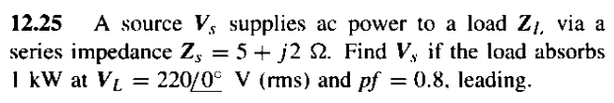

primero debemos calcular la impedancia de Zl, como nos dicen que el factor de potencia esta en adelanto, nos indica que es una cargar capacitiva, por lo tanto:

clc, clear, close all
format short g

zs = 5 + 2*j;
pl = 1000;
vl = 220;
pf = 0.8;

q1 = pl*tan(-acos(pf))

q1 =          -750


teniendo la potencia reactiva y activa de la carga podemos saber la potencia compleja:

sl = pl + q1*j 

sl =          1000 -        750i


Ahora que sabemos la potencia compleja de la carga, podemos saber la correinte rms que pasa:

Il = conj(sl/vl)

Il =        4.5455 +     3.4091i


zl = (vl^2)/(sl) %impedancia de la carga

zl =        30.976 +     23.232i


conociendo la correinte rms que pasa, podemos calcular la tension en la impedancia en serie con la carga:

vzs = Il*zs;
vzs_fasor = [abs(vzs) angle(vzs)*180/pi]

vzs_fasor =        30.598       58.671


para calcular Vs por LTK sabemso que es la suma de las tensiones ne las cargas:

vs = vzs + vl;
vs_fasor = [abs(vs) angle(vs)*180/pi]

vs_fasor =        237.35        6.322


lo verificamos en el simulador